# Ackermann Steering: Circular Trajectory Analysis

Date: May 1, 2026

**Title:** Comparison of Steering Angle Initialization vs. Rate-Based Control

**Description:** This script explores the ackermannKinematics class, which simulates a vehicle with a front-steering mechanism. It focuses on the distinction between controlling the vehicle via a static **Steering Angle** $\psi$—useful for steady-state circular motion—and controlling it via a **Steering Rate** $\dot{\psi}$, which simulates the physical rotation of the steering column over time.

**Note on MATLAB Classes:** Each model object (e.g., `ackermannKinematics`, `differentialDriveKinematics`) encapsulates the specific geometric constraints of the vehicle. By adjusting the `VehicleInputs` property, the `derivative` method is reconfigured to accept different control variables, allowing the user to switch between high-level path 

**Kinematic Foundation**

For a vehicle with a wheelbase $L$ to follow a circle of radius $R$, the required steering angle $\psi$ is calculated as:


$$\psi = \arctan\left(\frac{L}{R}\right)$$


**Method 1: Pre-turned Wheels (Ideal Geometry)**

In this method, we initialize the vehicle state with the steering angle already set to $\psi$. By setting the steering rate to $0$, the vehicle maintains a perfect constant radius from $t=0$.

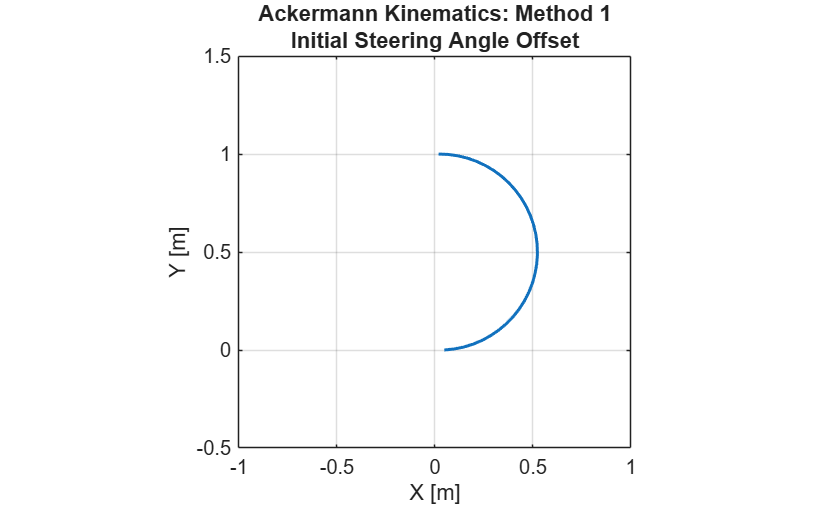

%% Setup Parameters
WheelBase = 0.2;
R = 0.5;                % Desired radius
v = 0.5;                % Constant linear velocity
dis = 2*pi*R;           % Full circumference
total_time = dis*0.5/v; % Half-circle duration
dt = 0.1;
t = 0:dt:total_time;

% Initialize Kinematic Model
kinematicModel = ackermannKinematics(WheelBase=WheelBase);

% Calculate fixed steering angle
psi = atan2(WheelBase, R);

% Set inputs: [Linear Velocity, Steering Rate]
% We set Rate to 0 because wheels are already at the correct angle
vel = [v, 0]; 

% Initialize Pose: [x, y, theta, psi]
% psi is set to the calculated angle immediately
initPose = [0, 0, 0, psi];
pose_cur = initPose';
POSE1 = zeros(length(t), 4);

%% Simulation Loop
for i = 1:length(t)
    % Calculate state derivatives based on current pose and velocity
    pose_dot = derivative(kinematicModel, initPose, vel);

    % Euler Integration: New State = Old State + (Change * TimeStep)
    pose_cur = pose_cur + pose_dot * dt;

    % Store and Update
    POSE1(i,:) = pose_cur'; 
    initPose = pose_cur;
end

% Visualization
figure(1);
plot(POSE1(:, 1), POSE1(:,2), 'LineWidth', 1.5)
title({'Ackermann Kinematics: Method 1','Initial Steering Angle Offset'})
xlabel('X [m]'); ylabel('Y [m]');
axis([-1 1 -0.5 1.5]); grid on; axis square;

## Method 2: Dynamic Steering Rate Control

This method starts with the wheels pointing straight ($\psi=0$). We calculate the required **Steering Rate** ($\dot{\psi}$) to reach the target angle within the first time step.

The control law used inside the loop is:


$$\dot{\psi} = \frac{\psi_{desired} - \psi_{current}}{dt}$$


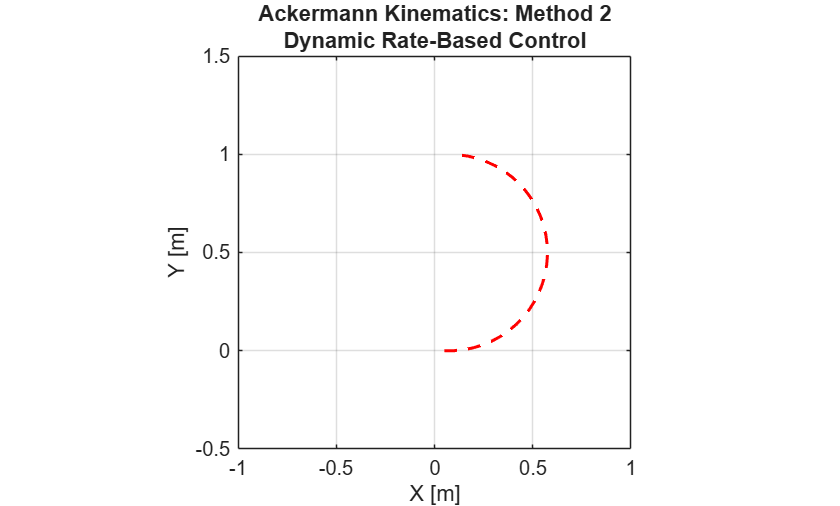

%% Setup Parameters
initPose = [0, 0, 0, 0]; % Start with wheels straight
desiredpsi = atan2(WheelBase, R);

% Calculate initial rate to reach desiredpsi in exactly one dt
psi_rate = (desiredpsi - initPose(4)) / dt;
vel = [v, psi_rate];
pose_cur = initPose';
POSE2 = zeros(length(t), 4);

%% Simulation Loop
for i = 1:length(t)
    % Compute derivatives
    pose_dot = derivative(kinematicModel, initPose, vel);

    % Euler Integration
    pose_cur = pose_cur + pose_dot * dt;
    POSE2(i,:) = pose_cur'; 
    initPose = pose_cur;

    % RE-CALCULATE CONTROL INPUT:
    % Once initPose(4) reaches desiredpsi, psi_rate becomes 0, locking the wheels.
    psi_rate = (desiredpsi - initPose(4)) / dt;
    vel = [v, psi_rate];
end

% Visualization
figure(2);
plot(POSE2(:, 1), POSE2(:,2), 'r--', 'LineWidth', 1.5)
title({'Ackermann Kinematics: Method 2', 'Dynamic Rate-Based Control'})
xlabel('X [m]'); ylabel('Y [m]');
axis([-1 1 -0.5 1.5]); grid on; axis square;